# Panel models (no cross-sections)

% cleaning

clear
close all
rehash path

addpath ../sandbox
addpath ../bear



## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

defaultColors = get(0, "defaultAxesColorOrder");


## Prepare data and a reduced-form model


inputTbx = tablex.fromCsv("panel_data_one_country.csv");

estimStart = datex.q(1972,1);
estimEnd = datex.q(2014,4);
estimSpan = datex.span(estimStart, estimEnd);

meta = model.Meta( ...
    endogenous=["YER", "HICSA", "STN"], ...
    units=["US"], ...
    exogenous=["Oil"], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=12, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);

dataH = model.DataHolder(meta, inputTbx);



## Select model


numSamples = 100;

% Mean OLS (not working for one country example - no country variations)
% estimatorR = estimator.MeanOLSPanel(meta);


% Normal Wishart Models
% estimatorR = estimator.NormalWishartPanel(meta);

% Random effect - Zellner Hong
estimatorR = estimator.ZellnerHongPanel(meta);

% Random effect - hierarchical
% estimatorR = estimator.HierarchicalPanel(meta);

estimatorR.Settings

ans =   ZellnerHongPanel with properties:

            Burnin: 0
         Exogenous: [9×2 logical]
    BlockExogenous: 0
    Autoregression: [9×1 double]
           Lambda1: 0.1000
           Lambda2: 0.5000
           Lambda3: 1
           Lambda4: [9×2 double]
           Lambda5: 1.0000e-03


## Reduced form model

modelR = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR ...
    , stabilityThreshold=Inf ...
);

rng(0)
modelR.initialize();
info = modelR.presample(numSamples);

 Presampling model.ReducedForm (ZellnerHongPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



% disp('Beta Median:')
% betaMedian = calcMedian(modelR,"beta");



## Specify exact zero restrictions 

exactZerosTbx = tablex.forExactZeros(modelR);
exactZerosTbx{"US_HICSA", "US_DEM"} = 0;
exactZerosTbx{"US_STN", "US_SUP"} = 0;
exactZerosTbx

exactZerosTbx = 9×9 table
                US_DEM    US_SUP    US_POL    EA_DEM    EA_SUP    EA_POL    UK_DEM    UK_SUP    UK_POL
                ______    ______    ______    ______    ______    ______    ______    ______    ______

    US_YER       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN  
    US_HICSA       0       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN  
    US_STN       NaN         0       NaN       NaN       NaN       NaN       NaN       NaN       NaN  
    EA_YER       NaN       NaN       NaN       NaN       NaN       NaN       NaN    

## Identify a SVAR using exact zero restrictions

identExactZeros = identifier.ExactZeros(exactZerosTbx);

identExactZeros

identExactZeros =   ExactZeros with properties:

    RestrictionTable: [9×9 table]
     NumRestrictions: 2
             Sampler: []
       SampleCounter: 0
          Candidator: []
    CandidateCounter: 0
     BeenInitialized: 0
      ShortClassName: 'ExactZeros'



modelS1 = model.Structural(reducedForm=modelR, identifier=identExactZeros);

modelS1

modelS1 =   Structural with properties:

             ReducedForm: [1×1 model.ReducedForm]
              Identifier: [1×1 identifier.ExactZeros]
              Presampled: {1×0 cell}
       PresampledCounter: 0
                    Meta: [1×1 model.Meta]
               Estimator: [1×1 estimator.ZellnerHongPanel]
              DataHolder: [1×1 model.DataHolder]
                 Sampler: []
           SampleCounter: 0
        CandidateCounter: 0
    IdentificationDrawer: @PlainPanelDrawersMixin.createDrawers/identificationDrawer
           HistoryDrawer: @PlainPanelDrawersMixin.createDrawers/historyDrawer
       ConditionalDrawer: @PlainPanelDrawersMixin.createDrawers/conditionalDrawer
     UnconditionalDrawer: @PlainPanelDrawersMixin.createDrawers/unconditionalDrawer
           NumPresampled: 0



modelS1.initialize();
info1 = modelS1.presample(100);

 Presampling model.Structural (ZellnerHongPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




respTbx1 = modelS1.simulateResponses();
respTbx1 = tablex.apply(respTbx1, extremesFunc);
respTbx1 = tablex.flatten(respTbx1);

respTbx1

respTbx1 = 16×27 timetable
     Time          US_YER___DEM               US_YER___SUP               US_YER___POL           US_HICSA___DEM         US_HICSA___SUP            US_HICSA___POL              US_STN___DEM            US_STN___SUP            US_STN___POL            EA_YER___DEM               EA_YER___SUP               EA_YER___POL           EA_HICSA___DEM          EA_HICSA___SUP             EA_HICSA___POL              EA_STN___DEM            EA_STN___SUP            EA_STN___POL            UK_YER___DEM               UK_YER___SUP               UK_YER___POL           UK_HICSA___DEM         U

## Identify a SVAR using sign restrictions

rng(0);

signStrings = [
    "$SHKRESP(2, 'US_YER', 'US_DEM') > 0"
    "$SHKRESP(2, 'US_HICSA', 'US_DEM') > 0"
    
    "$SHKRESP(3, 'US_YER', 'US_DEM') > 0"
    "$SHKRESP(3, 'US_HICSA', 'US_DEM') > 0"

    "$SHKRESP(2, 'US_YER', 'US_SUP') < 0"    
    "$SHKRESP(2, 'US_HICSA', 'US_SUP') > 0"

    "$SHKRESP(3, 'US_YER', 'US_SUP') < 0"
    "$SHKRESP(3, 'US_HICSA', 'US_SUP') > 0"
]

signStrings = 8×1 string array
    "$SHKRESP(2, 'US_YER', 'US_DEM') > 0"
    "$SHKRESP(2, 'US_HICSA', 'US_DEM') > 0"
    "$SHKRESP(3, 'US_YER', 'US_DEM') > 0"
    "$SHKRESP(3, 'US_HICSA', 'US_DEM') > 0"
    "$SHKRESP(2, 'US_YER', 'US_SUP') < 0"
    "$SHKRESP(2, 'US_HICSA', 'US_SUP') > 0"
    "$SHKRESP(3, 'US_YER', 'US_SUP') < 0"
    "$SHKRESP(3, 'US_HICSA', 'US_SUP') > 0"



identVerifiables = identifier.Verifiables( ...
    signStrings, ...
    maxCandidates=50, ...
    shortCircuit=false ...
);

modelS2 = model.Structural( ...
    reducedForm=modelR, ...
    identifier=identVerifiables ...
);

modelS2

modelS2 =   Structural with properties:

             ReducedForm: [1×1 model.ReducedForm]
              Identifier: [1×1 identifier.Verifiables]
              Presampled: {1×0 cell}
       PresampledCounter: 0
                    Meta: [1×1 model.Meta]
               Estimator: [1×1 estimator.ZellnerHongPanel]
              DataHolder: [1×1 model.DataHolder]
                 Sampler: []
           SampleCounter: 0
        CandidateCounter: 0
    IdentificationDrawer: @PlainPanelDrawersMixin.createDrawers/identificationDrawer
           HistoryDrawer: @PlainPanelDrawersMixin.createDrawers/historyDrawer
       ConditionalDrawer: @PlainPanelDrawersMixin.createDrawers/conditionalDrawer
     UnconditionalDrawer: @PlainPanelDrawersMixin.createDrawers/unconditionalDrawer
           NumPresampled: 0



modelS2.initialize();
info2 = modelS2.presample(100);

 Presampling model.Structural (ZellnerHongPanel) [100]
 ◼―――――――――――――――――――――――――――――――――――――――――――――――――  0% 

Error using  * 
Arguments must be 2-D, or at least one argument must be scalar. Use TIMES (.*) for elementwise multiplication, use PAGEMTIMES to apply matrix multiplication to the pages of N-D arrays,
or use TENSORPROD to find a product between two N-D arrays.

Error in system.calculateResiduals (line 42)
        U(t, :) = Y(t, :) - L(t, :) * A{t} - X(t, :) * C{t};

Error in 

info2

respTbx2 = modelS2.simulateResponses();
respTbx2 = tablex.apply(respTbx2, extremesFunc);
respTbx2 = tablex.flatten(respTbx2);

respTbx2

## Estimate residuals

resid = modelR.estimateResiduals();
resid

resid = 176×9 timetable
     Time      resid_US_YER    resid_US_HICSA    resid_US_STN    resid_EA_YER    resid_EA_HICSA    resid_EA_STN    resid_UK_YER    resid_UK_HICSA    resid_UK_STN
    _______    ____________    ______________    ____________    ____________    ______________    ____________    ____________    ______________    ____________

    1971-Q1    1×100 double     1×100 double     1×100 double    1×100 double     1×100 double     1×100 double    1×100 double     1×100 double     1×100 double
    1971-Q2    1×100 double     1×100 double     1×100 double    1×100 double     1×100 double     1×100 double    

## Run unconditional forecast


fcastStart = datex.shift(estimEnd, -9);
fcastEnd = datex.shift(estimEnd, 0);
fcastSpan = datex.span(fcastStart, fcastEnd);

fcast = modelR.forecast(fcastSpan);


## Indentify a SVAR using Cholesky (without reordering)


identChol = identifier.Cholesky(order=["HICSA", "STN"]);

modelS = model.Structural(reducedForm=modelR, identifier=identChol);
modelS.initialize();
info = modelS.presample(numSamples);

 Presampling model.Structural (ZellnerHongPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



## Simulate shock responses


resp = modelS.simulateResponses();


## Plot results

respTbx = tablex.apply(resp, prctileFunc);
respTbx = tablex.flatten(respTbx);

respTbx

respTbx = 16×27 timetable
     Time                 US_YER___DEM                          US_YER___SUP                            US_YER___POL                        US_HICSA___DEM                       US_HICSA___SUP                          US_HICSA___POL                          US_STN___DEM                           US_STN___SUP                        US_STN___POL                        EA_YER___DEM                           EA_YER___SUP                          EA_YER___POL                         EA_HICSA___DEM                        EA_HICSA___SUP                          EA_HICSA___POL                        EA_STN___DEM                        EA_STN___SUP                      

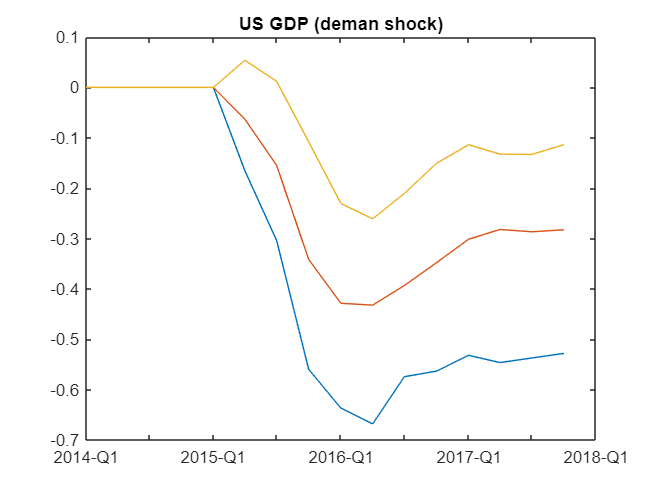


tablex.plot(respTbx,"US_YER___DEM");
title("US GDP (deman shock)");

## Uncoditional forecast

fcastStart = datex.shift(modelS.Meta.EstimationEnd, -10);
fcastEnd = datex.shift(modelS.Meta.EstimationEnd, 0);
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastTbx = modelS.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx);

fcastTbx

fcastTbx = 15×18 timetable
     Time         US_YER         US_HICSA         US_STN          EA_YER         EA_HICSA         EA_STN          UK_YER         UK_HICSA         UK_STN       resid_US_YER    resid_US_HICSA    resid_US_STN    resid_EA_YER    resid_EA_HICSA    resid_EA_STN    resid_UK_YER    resid_UK_HICSA    resid_UK_STN
    _______    ____________    ____________    ____________    ____________    ____________    ____________    ____________    ____________    ____________    _______

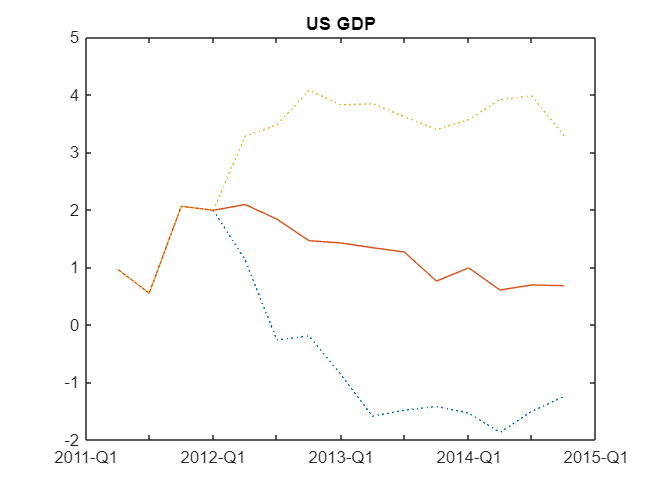


tablex.plot( ...
    fcastPrctileTbx, "US_YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);
title("US GDP");

## Calcuate FEVD

fevd = modelS.calculateFEVD();


# Conditional forecast

## Create forecast assumptions

fcastStart = datex.shift(estimEnd, 1);
fcastEnd = datex.shift(estimEnd, 12);
fcastSpan = datex.span(fcastStart, fcastEnd);
initStart = datex.shift(fcastStart, -modelS.Meta.Order);

[dataTbx, planTbx] = tablex.forConditional(modelS, fcastSpan);

dataTbx{datex("2015-Q1"), "US_YER"} = -1.5;
dataTbx{datex("2015-Q4"), "US_HICSA"} = 5.5;

dataTbx{:, "Oil"} = inputTbx{end, "Oil"};

dataTbx

dataTbx = 12×10 timetable
     Time      US_YER    US_HICSA    US_STN    EA_YER    EA_HICSA    EA_STN    UK_YER    UK_HICSA    UK_STN     Oil 
    _______    ______    ________    ______    ______    ________    ______    ______    ________    ______    _____

    2015-Q1     -1.5       NaN        NaN       NaN        NaN        NaN       NaN        NaN        NaN      94.32
    2015-Q2      NaN       NaN        NaN       NaN        NaN        NaN       NaN        NaN        NaN      94.32
    2015-Q3      NaN       NaN        NaN       NaN        NaN        NaN       

planTbx

planTbx = 12×9 timetable
     Time      US_YER    US_HICSA    US_STN    EA_YER    EA_HICSA    EA_STN    UK_YER    UK_HICSA    UK_STN
    _______    ______    ________    ______    ______    ________    ______    ______    ________    ______

    2015-Q1      ""         ""         ""        ""         ""         ""        ""         ""         ""  
    2015-Q2      ""         ""         ""        ""         ""         ""        ""         ""         ""  
    2015-Q3      ""         ""         ""        ""         ""         ""        ""         ""         ""  
    2015-Q4      ""       

## Run across-the-board vs selective conditions forecasts

planTbx{datex.q(2015,1), "US_YER"} = "US_DEM US_POL";
planTbx{datex.q(2015,4), "US_HICSA"} = "US_DEM US_SUP";
planTbx

planTbx = 12×9 timetable
     Time          US_YER            US_HICSA        US_STN    EA_YER    EA_HICSA    EA_STN    UK_YER    UK_HICSA    UK_STN
    _______    _______________    _______________    ______    ______    ________    ______    ______    ________    ______

    2015-Q1    "US_DEM US_POL"    ""                   ""        ""         ""         ""        ""         ""         ""  
    2015-Q2    ""                 ""                   ""        ""         ""         ""        ""         ""         ""  
    2015-Q3    ""                 ""                   ""        ""         ""         


rng(0);
cfcastTbx1 = modelS.conditionalForecast(fcastSpan, conditions=dataTbx, plan=[]);

 Conditional forecast [100]
 ◼―――――――――――――――――――――――――――――――――――――――――――――――――  0% 

Error using  .' 
TRANSPOSE does not support N-D arrays. Use PAGETRANSPOSE/PAGECTRANSPOSE to transpose pages or PERMUTE to reorder dimensions of N-D arrays.

Error in conditional.forecast (line 18)
    Y = transpose(flipud(initY));

Error in model/Structural/conditionalForecast (

cfcastPrctilesTbx1 = tablex.apply(cfcastTbx1, prctileFunc);

rng(0);
cfcastTbx2 = modelS.conditionalForecast(fcastSpan, conditions=dataTbx, plan=planTbx);
cfcastPrctilesTbx2 = tablex.apply(cfcastTbx2, prctileFunc);



plotSettings = { ...
   {"color"}, {defaultColors(2,:); defaultColors(1,:); defaultColors(2,:)},  ...
   {"lineStyle"}, {":";"-";":"}, ...
};

ch = visual.Chartpack( ...
    span=datex.span(initStart, fcastEnd), ...
    namesToPlot=[modelS.Meta.EndogenousNames, modelS.Meta.ShockNames], ...
    plotSettings=plotSettings ...
);

ch.Captions = "Across-the-board conditional forecast";
ch.plot(cfcastPrctilesTbx1);

ch.Captions = "Selective conditional forecast";
ch.plot(cfcastPrctilesTbx2);